# 一、Yolov2多目标猫狗检测（自动确定anchor）

#### 注：图像大小最好统一后，再进行标注工作。

## 1.1 导入数据

clear;clc;
load('gTruth.mat');

#### 1.1.1 更改标签路径

% currentPath = "G:\MATLAB\YOLO模型\YOLOv3\数据集";%原数据集路径
% newPath = "G:\MATLAB\YOLO模型\YOLOv3\植物叶片检测\训练集";%新的数据集路径
% alternativePaths = {[currentPath newPath]};
% unresolvedPaths = changeFilePaths(gTruth,alternativePaths)%替换后会显示空数组

#### 1.1.2 读取图像位置

trainingfiles = gTruth.DataSource.Source;         %图像位置
traininglabel = gTruth.LabelData;                 %图像标签

Create an imageDatastore using the files from the table.

imgfiles = imageDatastore(trainingfiles);

Create a boxLabelDatastore using the label columns from the table.

imglabel = boxLabelDatastore(traininglabel);

Combine the datastores.

ds = combine(imgfiles, imglabel);

## 1.2 可视化标记框

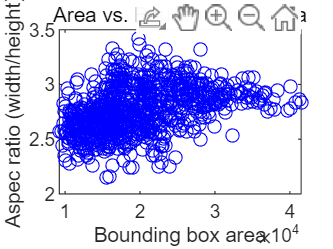

% Concatenate all bounding boxes
allBoxes = cell2mat(reshape(table2array(gTruth.LabelData),[],1));

% Plot bounding box area vs. aspect ratio
aspectRatio = allBoxes(:,3) ./ allBoxes(:,4);
area = prod(allBoxes(:,3:4),2);

figure
%scatter(area,aspectRatio)
plot(area,aspectRatio,"ro","Color",[0 0 1])
xlabel("Bounding box area")
ylabel("Aspec ratio (width/height)");
title("Area vs. Bounding box area")

## 1.3 确定框的数量

% Clustering into 4 groups
numAnchors = 40;

% Clustering data with K-Medoids
[clusterAssignments, anchorBoxes, sumd] = kmedoids(allBoxes(:,3:4),numAnchors,'Distance',@iouDistanceMetric);

% show the size of anchor boxes
disp(anchorBoxes);

   273    90
   219    82
   340   120
   247    83
   175    71
   209    82
   287    95
   313   107
   204    79
   229    84
   230    89
   278   101
   233    76
   195    73
   184    67
   258    92
   195    80
   236    97
   276    95
   246    87
   215    79
   213    76
   289   100
   161    65
   232    80
   300   103
   203    76
   211    86
   322   112
   224    75
   259    81
   257    97
   202    70
   216    72
   186    71
   266    86
   173    67
   242    91
   188    75
   171    63



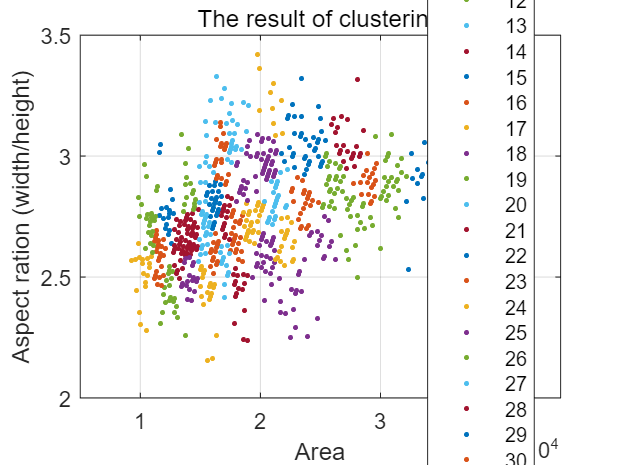


% plot the result of clustering
figure
gscatter(area,aspectRatio,clusterAssignments);
title("The result of clustering")
xlabel("Area")
ylabel("Aspect ration (width/height)");
grid


% Cumulative addition
counts = accumarray(clusterAssignments, ones(length(clusterAssignments),1),[],@(x)sum(x)-1);

%Calculate mean IoU
meanIoU = mean(1 - sumd./(counts));
disp("mean IoU : " + meanIoU);

mean IoU : 0.9718


## 1.4 确认anchor box数量与平均IoU的关系

Increasing the anchor box improves the average IoU but increases the computational complexity.

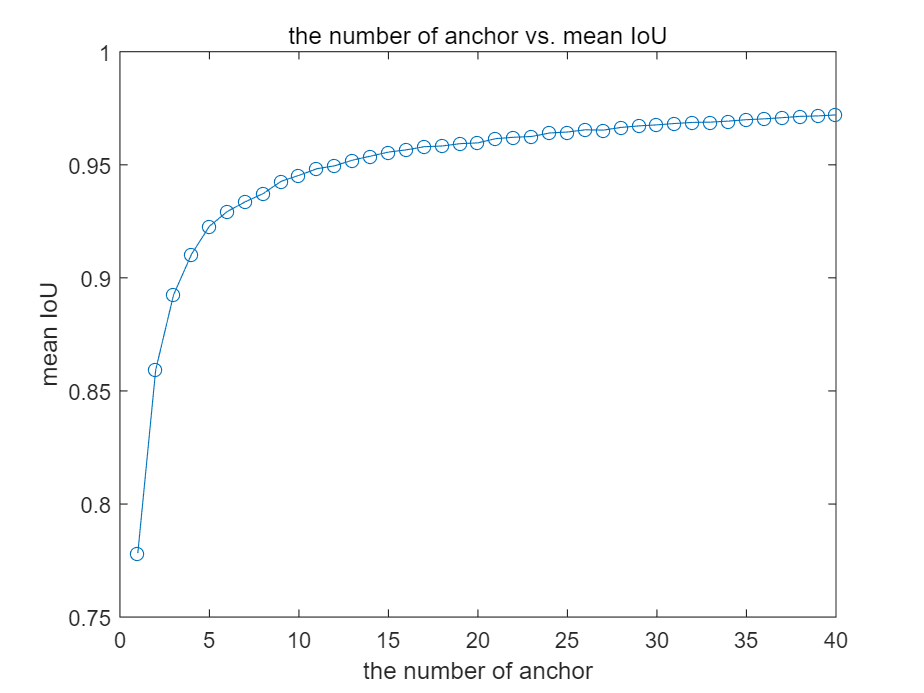


maxNumAnchors = 40;
for k = 1:maxNumAnchors
    
    % Clustering data with K-Medoids
    [clusterAssignments, ~, sumd] = kmedoids(allBoxes(:,3:4),k,'Distance',@iouDistanceMetric);
    
    % Calculate mean IoU
    counts = accumarray(clusterAssignments, ones(length(clusterAssignments),1),[],@(x)sum(x)-1);
    meanIoU(k) = mean(1 - sumd./(counts));
end

figure
plot(1:maxNumAnchors, meanIoU,'-o')
ylabel("mean IoU")
xlabel("the number of anchor")
title("the number of anchor vs. mean IoU")

## 1.5 搭建Yolov2模型

% load pretrained model
network = alexnet();
% Specify the layer to be used for feature extraction
featureLayer = 'pool5';
% input image size
imageSize =[224 224 3];%输入图像大小，可调整
% the number of classes
numClasses = width(gTruth.LabelData);
anchorBoxes(:,1) =anchorBoxes(:,1)*224/1280;%这里224对应调整后[224 224 3];410对应原始图像[720 1280 3]
anchorBoxes(:,2) =anchorBoxes(:,2)*224/720;
% define yolo v2 detector
lgraph = yolov2Layers(imageSize, numClasses, round(anchorBoxes), ...
    network, featureLayer);
% visualize network
%analyzeNetwork(lgraph)
options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.0001, ...
    'Verbose', true, 'MiniBatchSize', 32, 'MaxEpochs', 1000,...
    'Shuffle', 'every-epoch', 'VerboseFrequency', 30);

## 1.6 训练Yolo v2模型

doTraining = true;%把这里改为true即可训练
if doTraining
    rng('default');
    tic;
    [detector,info] = trainYOLOv2ObjectDetector(ds,lgraph,options);
    toc
    save('trainedYOLOv2Detector','detector','info');
else
    load('trainedYOLOv2Detector');
end

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* Front
* Left
* Right

在单 GPU 上训练。
正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　小批量损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０２　｜　　　　　　　８．０６　｜　　　　６４．９　｜　１．００００ｅ－０４　｜
｜　　　２　｜　　　３０　｜　　　　　００：００：１８　｜　　　　　　　２．９８　｜　　　　　８．９　｜　１．００００ｅ－０４　｜
｜　　　３　｜　　　６０　｜　　　　　００：００：３５　｜　　　　　　　１．８０　｜　　　　　３．２　｜　１．００００ｅ－０４　｜
｜　　　４　｜　　　９０　｜　　　　　００：００：５２　｜　　　　　　　１．４４　｜　　　　　２．１　｜　１．００００ｅ－０４　｜
｜　　　５　｜　　１２０　｜　　　　　００：０１：０８　｜　　　　　　　１．２２　｜　　　　　１．５　｜　１．００００ｅ－０４　｜
｜　　　６　｜　　１５０　｜　　　　　００：０１：２５　｜　　　　　　　１．０８　｜　　　　　１．２　｜　１．００００ｅ－０４　｜
｜　　　７　｜　　１８０　｜　　　　　００：０１：４２　｜　　　　　　　０．９８　｜　　　　　１．０　｜　１．００００ｅ－０４　｜
｜　　　８　｜　　２１０　｜　　　　　００：０１：５９　｜　　　　　　　０．９１　｜　　　　　０．８　｜　１．００００ｅ－０４　｜
｜　　　９　｜　　２４０　｜　　　　　００：０２：１

历时 17050.104046 秒。


## 1.7 使用训练好的模型测试

load("trainedYOLOv2Detector.mat")
load('gTruth.mat')

%addpath("D:\Thesis\toothdata\front_test\")
abboxes=[]


abboxes =

     []



bbboxes=[]


bbboxes =

     []



cbboxes=[]


cbboxes =

     []



dbboxes=[]


dbboxes =

     []



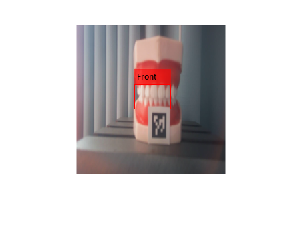

abboxes = 88

bbboxes = 90

cbboxes = 55

dbboxes = 38

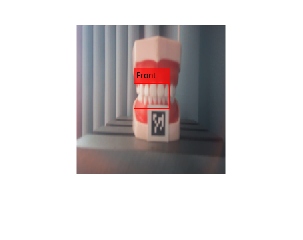

abboxes =     88    87


bbboxes =     90    88


cbboxes =     55    54


dbboxes =     38    39


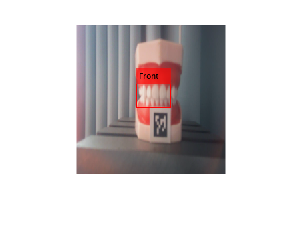

abboxes =     88    87    91


bbboxes =     90    88    89


cbboxes =     55    54    52


dbboxes =     38    39    37


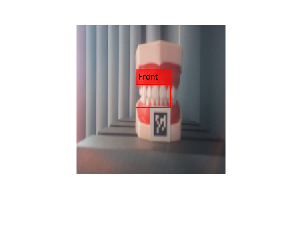

abboxes =     88    87    91    90


bbboxes =     90    88    89    90


cbboxes =     55    54    52    53


dbboxes =     38    39    37    36


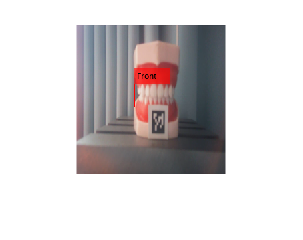

abboxes =     88    87    91    90    88


bbboxes =     90    88    89    90    89


cbboxes =     55    54    52    53    54


dbboxes =     38    39    37    36    36


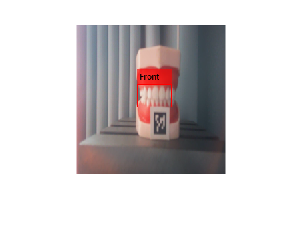

abboxes =     88    87    91    90    88    92


bbboxes =     90    88    89    90    89    90


cbboxes =     55    54    52    53    54    52


dbboxes =     38    39    37    36    36    35


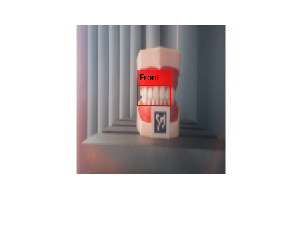

abboxes =     88    87    91    90    88    92    92


bbboxes =     90    88    89    90    89    90    91


cbboxes =     55    54    52    53    54    52    51


dbboxes =     38    39    37    36    36    35    32


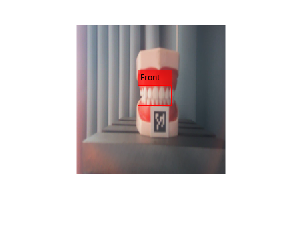

abboxes =     88    87    91    90    88    92    92    93


bbboxes =     90    88    89    90    89    90    91    91


cbboxes =     55    54    52    53    54    52    51    51


dbboxes =     38    39    37    36    36    35    32    32


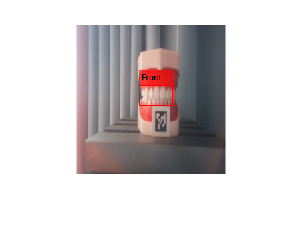

abboxes =     88    87    91    90    88    92    92    93    95


bbboxes =     90    88    89    90    89    90    91    91    91


cbboxes =     55    54    52    53    54    52    51    51    51


dbboxes =     38    39    37    36    36    35    32    32    32


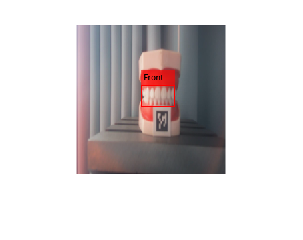

abboxes =     88    87    91    90    88    92    92    93    95    98


bbboxes =     90    88    89    90    89    90    91    91    91    91


cbboxes =     55    54    52    53    54    52    51    51    51    51


dbboxes =     38    39    37    36    36    35    32    32    32    33


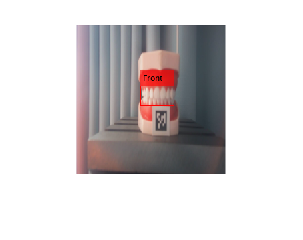

abboxes =     88    87    91    90    88    92    92    93    95    98    97


bbboxes =     90    88    89    90    89    90    91    91    91    91    92


cbboxes =     55    54    52    53    54    52    51    51    51    51    51


dbboxes =     38    39    37    36    36    35    32    32    32    33    31


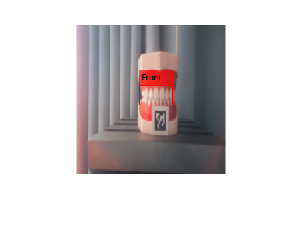

abboxes =     88    87    91    90    88    92    92    93    95    98    97    95


bbboxes =     90    88    89    90    89    90    91    91    91    91    92    91


cbboxes =     55    54    52    53    54    52    51    51    51    51    51    51


dbboxes =     38    39    37    36    36    35    32    32    32    33    31    31


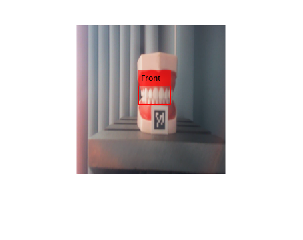

abboxes =     88    87    91    90    88    92    92    93    95    98    97    95    94


bbboxes =     90    88    89    90    89    90    91    91    91    91    92    91    92


cbboxes =     55    54    52    53    54    52    51    51    51    51    51    51    49


dbboxes =     38    39    37    36    36    35    32    32    32    33    31    31    29


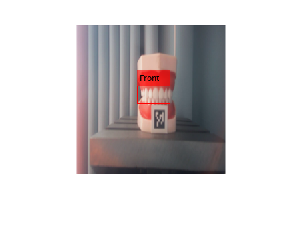

abboxes =     88    87    91    90    88    92    92    93    95    98    97    95    94    92


bbboxes =     90    88    89    90    89    90    91    91    91    91    92    91    92    92


cbboxes = 1×14
    55    54    52    53    54    52    51    51    51    51    51    51    49    50


dbboxes = 1×14
    38    39    37    36    36    35    32    32    32    33    31    31    29    28


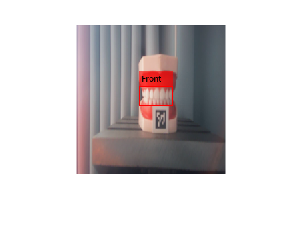

abboxes = 1×15
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95


bbboxes = 1×15
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93


cbboxes = 1×15
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51


dbboxes = 1×15
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30


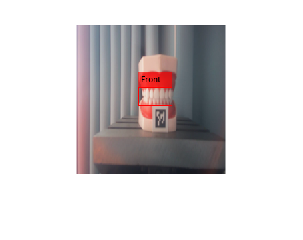

abboxes = 1×16
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94


bbboxes = 1×16
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94


cbboxes = 1×16
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51


dbboxes = 1×16
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29


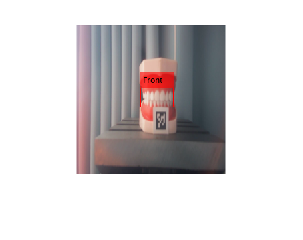

abboxes = 1×17
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97


bbboxes = 1×17
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95


cbboxes = 1×17
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50


dbboxes = 1×17
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30


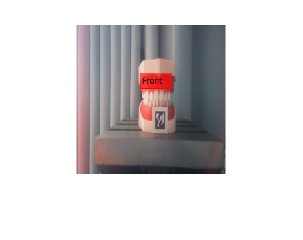

abboxes = 1×18
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96


bbboxes = 1×18
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96


cbboxes = 1×18
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49


dbboxes = 1×18
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29


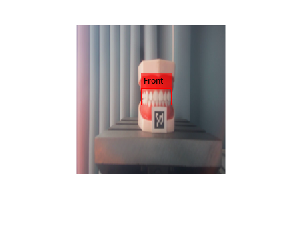

abboxes = 1×19
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98


bbboxes = 1×19
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96


cbboxes = 1×19
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46


dbboxes = 1×19
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26


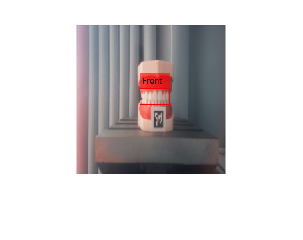

abboxes = 1×20
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96


bbboxes = 1×20
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96


cbboxes = 1×20
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45


dbboxes = 1×20
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25


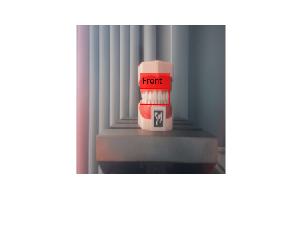

abboxes = 1×21
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96


bbboxes = 1×21
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96


cbboxes = 1×21
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45


dbboxes = 1×21
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25


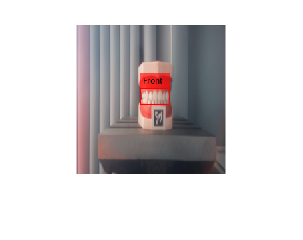

abboxes = 1×22
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97


bbboxes = 1×22
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96


cbboxes = 1×22
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44


dbboxes = 1×22
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25


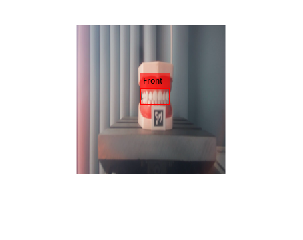

abboxes = 1×23
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97


bbboxes = 1×23
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96


cbboxes = 1×23
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44


dbboxes = 1×23
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25


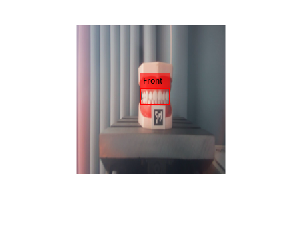

abboxes = 1×24
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97


bbboxes = 1×24
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96


cbboxes = 1×24
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44


dbboxes = 1×24
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25


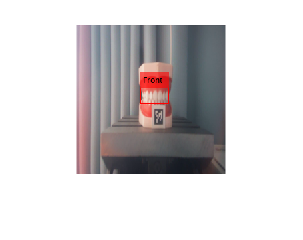

abboxes = 1×25
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97


bbboxes = 1×25
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95


cbboxes = 1×25
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43


dbboxes = 1×25
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25


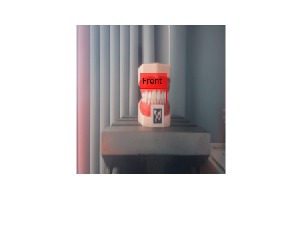

abboxes = 1×26
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96


bbboxes = 1×26
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96


cbboxes = 1×26
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41


dbboxes = 1×26
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23


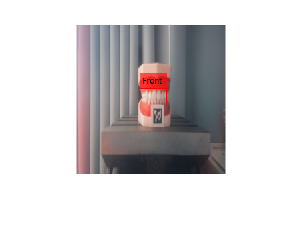

abboxes = 1×27
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96


bbboxes = 1×27
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96


cbboxes = 1×27
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41


dbboxes = 1×27
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23


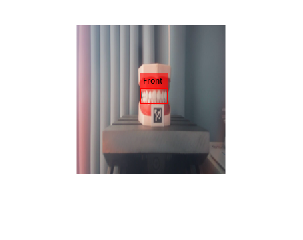

abboxes = 1×28
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97


bbboxes = 1×28
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96


cbboxes = 1×28
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41


dbboxes = 1×28
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24


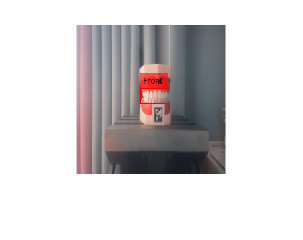

abboxes = 1×29
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97


bbboxes = 1×29
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96


cbboxes = 1×29
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42


dbboxes = 1×29
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24


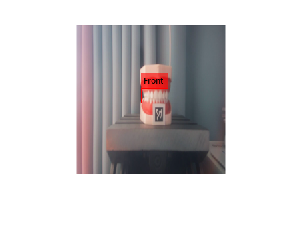

abboxes = 1×30
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×30
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×30
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×30
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


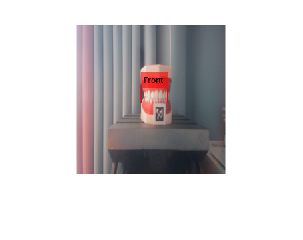

abboxes = 1×31
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×31
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×31
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×31
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


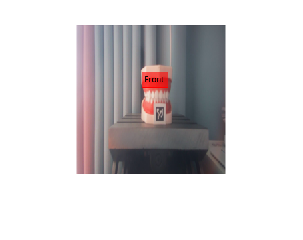

abboxes = 1×32
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×32
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×32
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×32
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


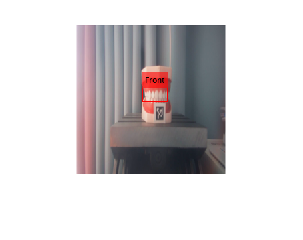

abboxes = 1×33
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×33
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×33
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×33
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


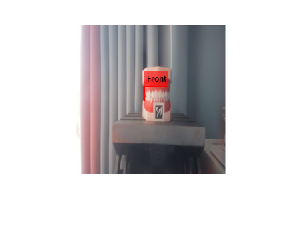

abboxes = 1×34
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×34
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×34
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×34
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


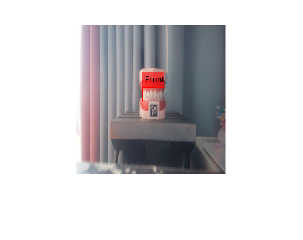

abboxes = 1×35
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×35
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×35
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×35
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


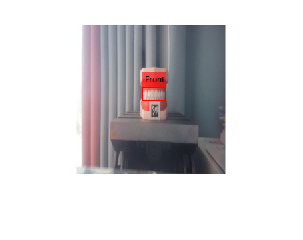

abboxes = 1×36
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×36
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×36
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×36
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


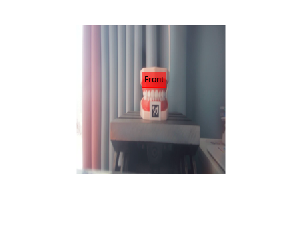

abboxes = 1×37
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×37
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×37
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×37
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


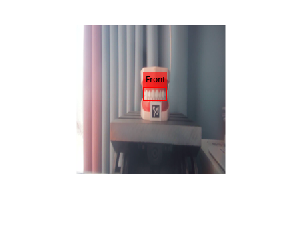

abboxes = 1×38
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×38
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×38
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×38
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


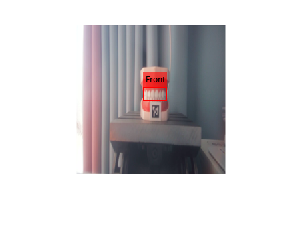

abboxes = 1×39
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×39
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×39
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×39
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


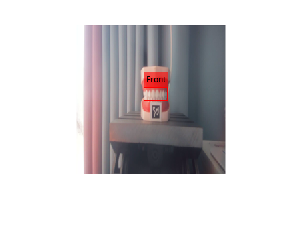

abboxes = 1×40
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×40
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×40
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×40
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


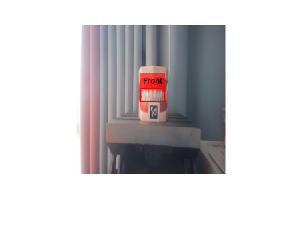

abboxes = 1×41
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×41
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×41
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×41
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


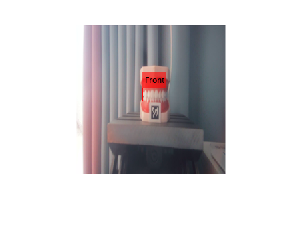

abboxes = 1×42
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×42
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×42
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×42
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


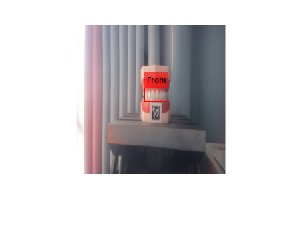

abboxes = 1×43
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×43
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×43
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×43
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


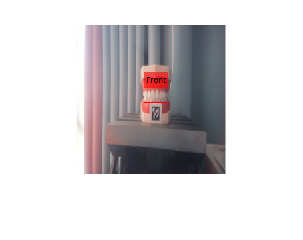

abboxes = 1×44
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×44
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×44
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×44
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


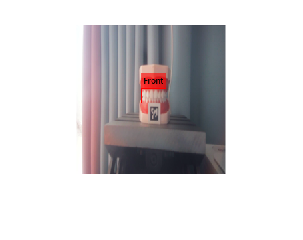

abboxes = 1×45
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×45
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×45
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×45
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


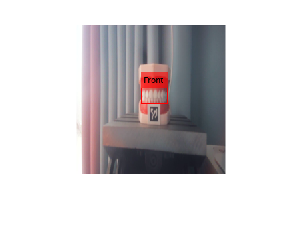

abboxes = 1×46
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×46
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×46
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×46
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


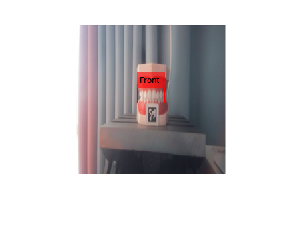

abboxes = 1×47
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×47
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×47
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×47
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


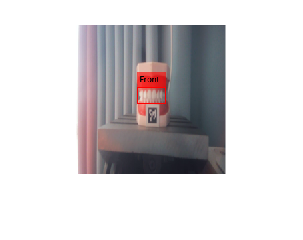

abboxes = 1×48
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×48
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×48
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×48
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


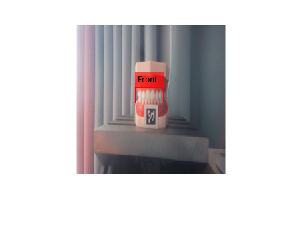

abboxes = 1×49
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×49
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×49
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×49
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


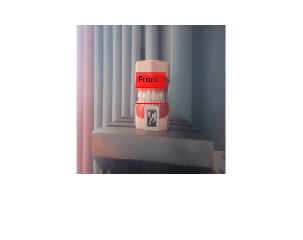

abboxes = 1×50
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×50
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×50
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×50
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


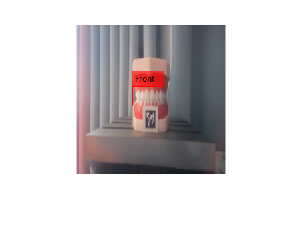

abboxes = 1×51
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×51
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×51
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×51
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


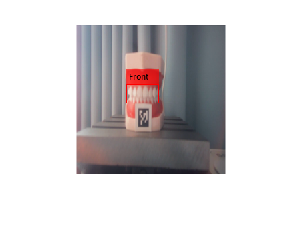

abboxes = 1×52
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×52
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×52
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×52
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


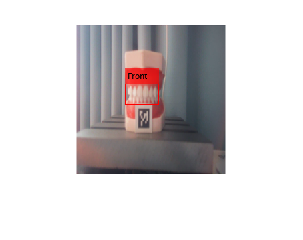

abboxes = 1×53
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×53
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×53
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×53
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


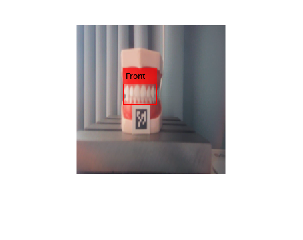

abboxes = 1×54
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×54
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×54
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×54
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


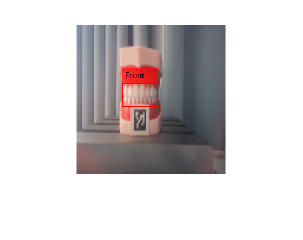

abboxes = 1×55
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×55
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×55
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×55
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


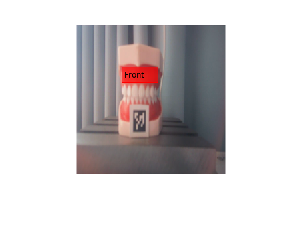

abboxes = 1×56
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×56
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×56
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×56
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


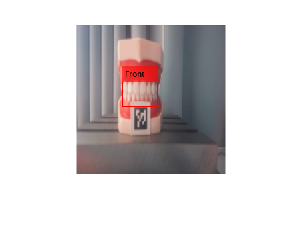

abboxes = 1×57
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×57
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×57
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×57
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


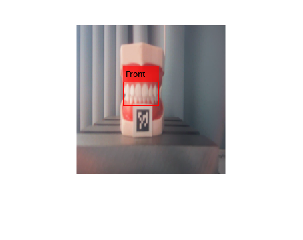

abboxes = 1×58
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×58
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×58
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×58
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


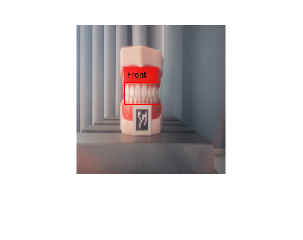

abboxes = 1×59
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×59
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×59
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×59
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


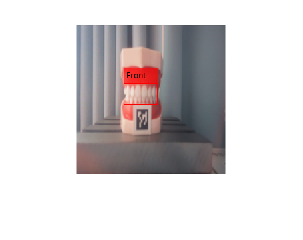

abboxes = 1×60
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×60
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×60
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×60
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


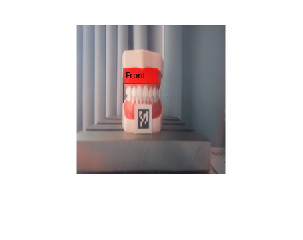

abboxes = 1×61
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×61
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×61
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×61
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


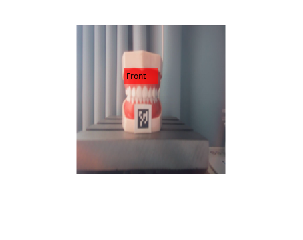

abboxes = 1×62
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×62
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×62
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×62
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


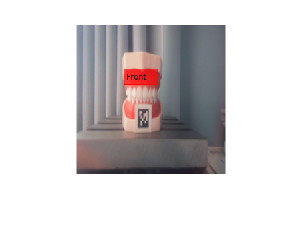

abboxes = 1×63
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×63
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×63
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×63
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


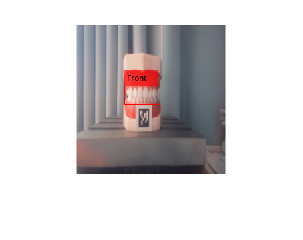

abboxes = 1×64
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×64
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×64
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×64
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


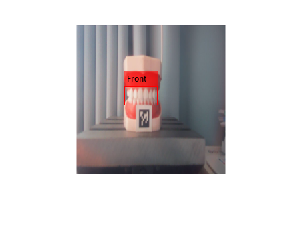

abboxes = 1×65
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×65
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×65
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×65
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


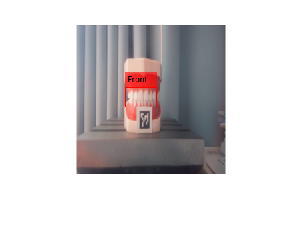

abboxes = 1×66
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×66
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×66
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×66
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


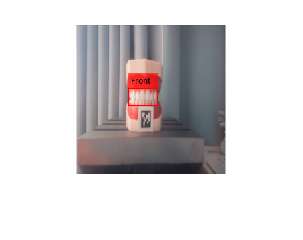

abboxes = 1×67
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×67
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×67
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×67
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


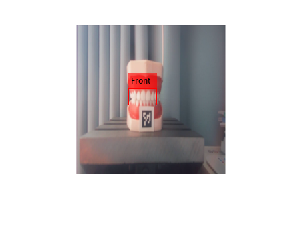

abboxes = 1×68
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×68
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×68
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×68
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


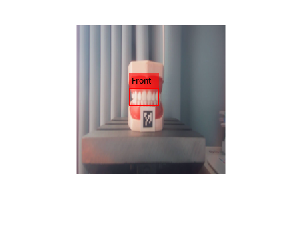

abboxes = 1×69
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×69
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×69
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×69
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


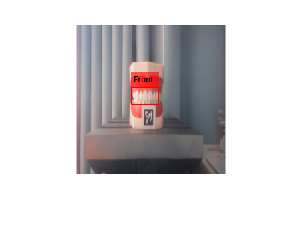

abboxes = 1×70
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×70
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×70
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×70
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


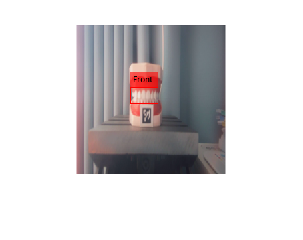

abboxes = 1×71
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×71
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×71
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×71
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


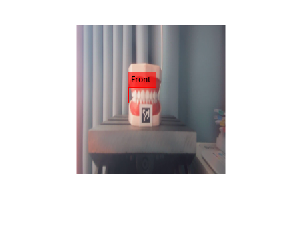

abboxes = 1×72
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×72
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×72
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×72
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


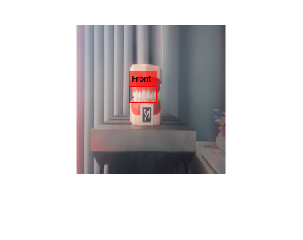

abboxes = 1×73
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×73
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×73
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×73
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


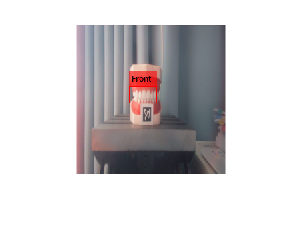

abboxes = 1×74
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×74
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×74
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×74
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


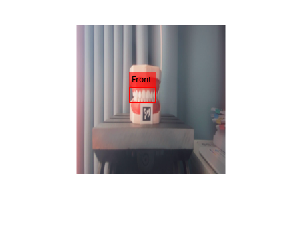

abboxes = 1×75
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×75
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×75
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×75
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


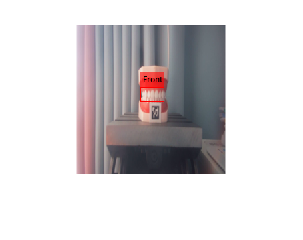

abboxes = 1×76
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×76
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×76
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×76
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


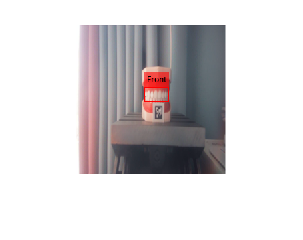

abboxes = 1×77
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×77
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×77
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×77
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


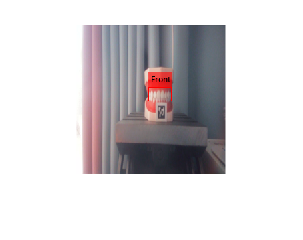

abboxes = 1×78
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×78
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×78
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×78
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


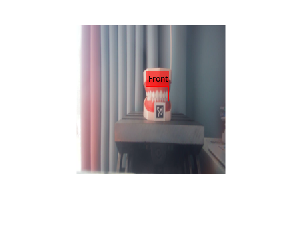

abboxes = 1×79
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×79
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×79
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×79
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


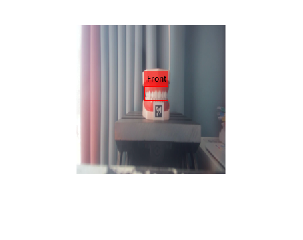

abboxes = 1×80
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×80
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×80
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×80
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


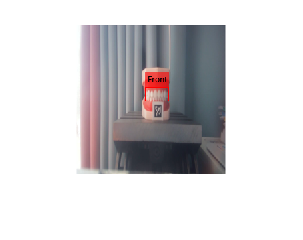

abboxes = 1×81
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×81
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×81
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×81
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


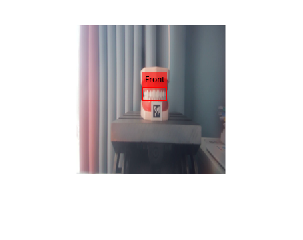

abboxes = 1×82
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×82
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×82
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×82
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


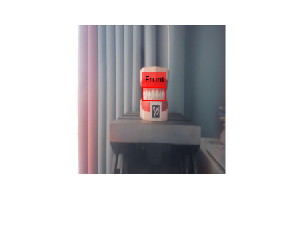

abboxes = 1×83
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×83
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×83
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×83
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


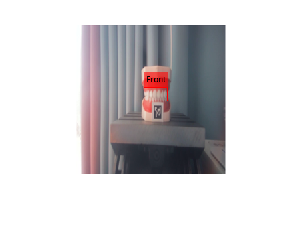

abboxes = 1×84
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×84
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×84
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×84
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


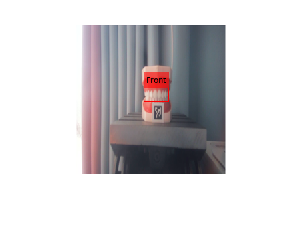

abboxes = 1×85
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×85
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×85
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×85
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


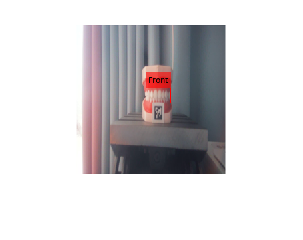

abboxes = 1×86
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×86
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×86
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×86
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


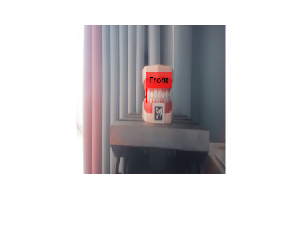

abboxes = 1×87
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×87
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×87
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×87
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


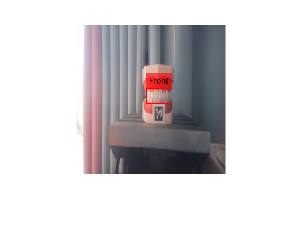

abboxes = 1×88
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×88
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×88
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×88
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


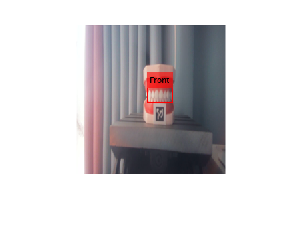

abboxes = 1×89
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×89
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×89
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×89
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


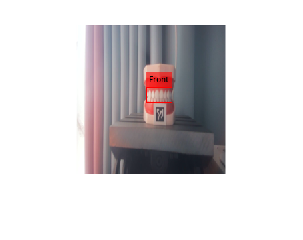

abboxes = 1×90
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×90
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×90
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×90
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


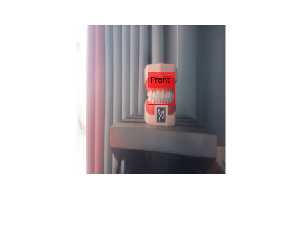

abboxes = 1×91
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×91
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×91
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×91
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


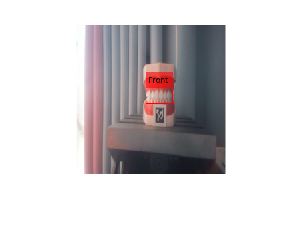

abboxes = 1×92
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×92
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×92
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×92
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


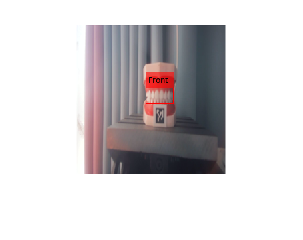

abboxes = 1×93
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×93
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×93
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×93
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


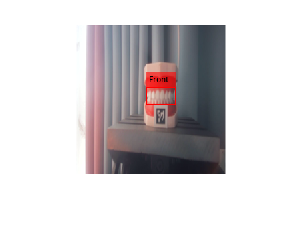

abboxes = 1×94
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×94
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×94
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×94
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


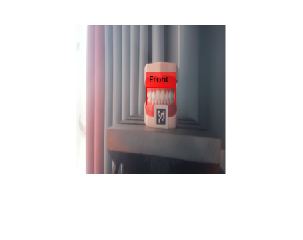

abboxes = 1×95
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×95
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×95
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×95
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


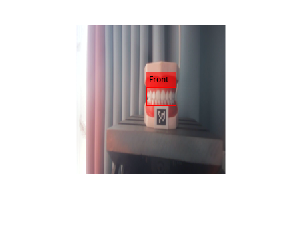

abboxes = 1×96
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×96
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×96
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×96
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


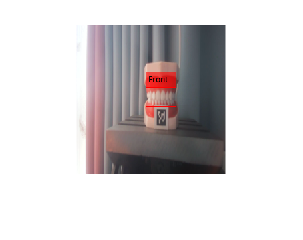

abboxes = 1×97
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×97
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×97
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×97
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


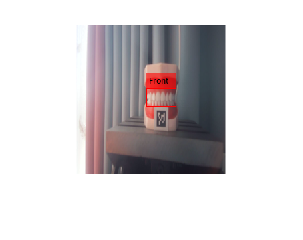

abboxes = 1×98
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×98
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×98
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×98
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


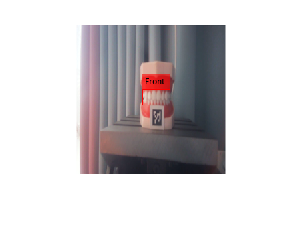

abboxes = 1×99
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×99
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×99
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×99
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


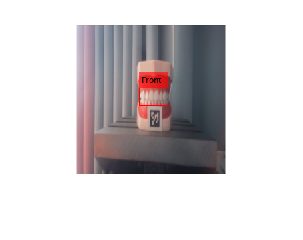

abboxes = 1×100
    88    87    91    90    88    92    92    93    95    98    97    95    94    92    95    94    97    96    98    96    96    97    97    97    97    96    96    97    97    98


bbboxes = 1×100
    90    88    89    90    89    90    91    91    91    91    92    91    92    92    93    94    95    96    96    96    96    96    96    96    95    96    96    96    96    96


cbboxes = 1×100
    55    54    52    53    54    52    51    51    51    51    51    51    49    50    51    51    50    49    46    45    45    44    44    44    43    41    41    41    42    41


dbboxes = 1×100
    38    39    37    36    36    35    32    32    32    33    31    31    29    28    30    29    30    29    26    25    25    25    25    25    25    23    23    24    24    23


SamplePath1 =  'D:\Thesis\toothdata\front_test\';  %存储图像的路径
fileExt = '*.png';  %待读取图像的后缀名
%获取所有路径
files = dir(fullfile(SamplePath1,fileExt)); 
len1 = size(files,1);
%遍历路径下每一幅图像
for i=1:len1;
    fileName = strcat(SamplePath1,files(i).name);
    image = imread(fileName);
    I = imresize(image,[224 224]);
    % 使用模型检测
    [bboxes, scores, labels] = detect(detector, I);
    % Colormap index generation for labels
    [~,ind] = ismember(labels,gTruth.LabelDefinitions.Name);
    % 展示结果
    % 定义框颜色 = 分类数量
    cmaps = [
        255 000 000;         %黄色
        000 255 000;
        000 000 255%红色
        ];
    if ~isempty(labels)
        detectedImg = insertObjectAnnotation(I, 'Rectangle', bboxes, cellstr(labels),...
            'Color',cmaps(ind,:));
        figure
        imshow(detectedImg)
        abboxes(end+1)=bboxes(1)
        bbboxes(end+1)=bboxes(2)
        cbboxes(end+1)=bboxes(3)
        dbboxes(end+1)=bboxes(4)
%         istr=num2str(i)
%         begin=strcat('A',istr)
%         %final=strcat(istr,'D')
%         xlswrite('bboxes.xlsx',bboxes,'sheet2',begin);


        %fprintf(bboxes[1])
    else
        imshow(I)
        title("No object")
    end
    norubbish_data(:,:,:,i) = I;
end

%n = randi(80) ;%随机选取一张图像识别
%I = imresize(imread(cell2mat(gTruth.DataSource.Source(n))),[224 224]);
I=imresize(imread("D:\Thesis\toothdata\right_test\ssnapshot14239.png"),[224,224])

I = 224×224×3 uint8 数组
I(:,:,1) =

   167   157   150   154   148   144   161   168   166   163   159   153   148   142   137   133   129   125   123   119   110   114   146   158   161   160   156   153   147   140   133   131   129   125   121   120   119   106   107   145   175   172   170   163   156   143   141   139   132   127   124   120   120   116   105   114   158   171   170   166   158   151   143   136   132   128   124   116   115   119   114   103   103   149   163   163   161   157   152   146   138   133   129   124   118   115   114   108    96    77    77    77    73    75    87   104   130   146   161   166   166   160   164   162   160   156   148   141   135   130   124   117   116   113   111   103    86    74    72    71    69    69    73    77    84    94    98   101   106   112   113   117   122   125   127   129   135   138   142   146   149   179   189   162   138   136   134   130   130   124   122   121   117   116   114   109   110   109   108   107   10

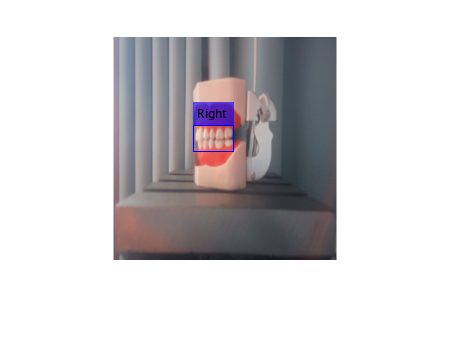

% 使用模型检测 466,285,228,86]
[bboxes, scores, labels] = detect(detector, I);
% Colormap index generation for labels
[~,ind] = ismember(labels,gTruth.LabelDefinitions.Name);
% 展示结果
% 定义框颜色 = 分类数量
cmaps = [
    255 000 000;         %黄色
    000 255 000;
    000 000 255%红色
    ];
if ~isempty(labels)
    detectedImg = insertObjectAnnotation(I, 'Rectangle', bboxes, cellstr(labels),...
    'Color',cmaps(ind,:));
    figure
    imshow(detectedImg)
else
    imshow(I)
    title("未识别到目标物")
end

## 支持函数

function dist = iouDistanceMetric(boxWidthHeight,allBoxWidthHeight)
% Calculate metric as distance based on IoU

% add x, y to caluculate IoU as bounding box
boxWidthHeight = prefixXYCoordinates(boxWidthHeight);
allBoxWidthHeight = prefixXYCoordinates(allBoxWidthHeight);

% Convert IoU to distance
dist = 1 - bboxOverlapRatio(allBoxWidthHeight, boxWidthHeight);
end

function boxWidthHeight = prefixXYCoordinates(boxWidthHeight)
% add x, y to caluculate IoU as bounding box
n = size(boxWidthHeight,1);
boxWidthHeight = [ones(n,2) boxWidthHeight];
end